clc
clear
freq = 1/333;
m = 0.35;
names = ["nosex", "nosey", "nosez", "tailx", "taily", "tailz", "leftx", "lefty", "leftz", "rightx",...
    "righty", "rightz", "midx", "midy", "midz", "gx", "gy", "gz", "ax", "ay", "az"];

file_names = [...
    "1_dynamic_dihedral_s1",...
    "2_dynamic_dihedral_s1",...
    "3_dynamic_dihedral_s1",...
    ];

data = struct;
for i = file_names
    data.("a"+i) = readtable(i+".csv");
    data.("a"+i).Properties.VariableNames = names;
    
    diff_Z = data.("a"+i).tailz - data.("a"+i).midz;
    diff_Y = data.("a"+i).taily - data.("a"+i).midy;
    diff_X = data.("a"+i).tailx - data.("a"+i).midx;
    data.("a"+i).pitch = atand(diff_Z./diff_Y);
    data.("a"+i).yaw = atand(diff_Y./diff_X);
    
    diff_Z = data.("a"+i).leftz - data.("a"+i).rightz;
    diff_Y = data.("a"+i).lefty - data.("a"+i).righty;
    diff_X = data.("a"+i).leftx - data.("a"+i).rightx;
    data.("a"+i).roll = atand( diff_Z./diff_X);
    
    data.("a"+i).t = (freq:freq:(freq)*length(data.("a"+i).gy))';
    
    data.("a"+i).vx = [0; diff(0.5 * (data.("a"+i).midx + data.("a"+i).tailx)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).vy = [0; diff(0.5 * (data.("a"+i).midy + data.("a"+i).taily)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).vz = [0; diff(0.5 * (data.("a"+i).midz + data.("a"+i).tailz)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).v = smooth(vecnorm([data.("a"+i).vx, data.("a"+i).vy, data.("a"+i).vz]')',10, 'sgolay');
    
    data.("a"+i).glide_angle = smooth(atand(data.("a"+i).vz./data.("a"+i).vy),40, 'sgolay');
    data.("a"+i).AoA = data.("a"+i).pitch - data.("a"+i).glide_angle;
    
    data.("a"+i).a_x = ( data.("a"+i).az .* cosd(data.("a"+i).glide_angle) + data.("a"+i).ay) ./ (cosd(data.("a"+i).glide_angle) .* cosd(data.("a"+i).glide_angle) - sind(data.("a"+i).glide_angle));
    data.("a"+i).a_y = ( data.("a"+i).ay + data.("a"+i).a_x .* sind(data.("a"+i).glide_angle) )./cosd(data.("a"+i).glide_angle);
    
    data.("a"+i).lift = smooth(data.("a"+i).t, data.("a"+i).a_x, 20, 'sgolay')*m;
    data.("a"+i).drag = smooth(data.("a"+i).t, data.("a"+i).a_y, 20, 'sgolay')*m;
end

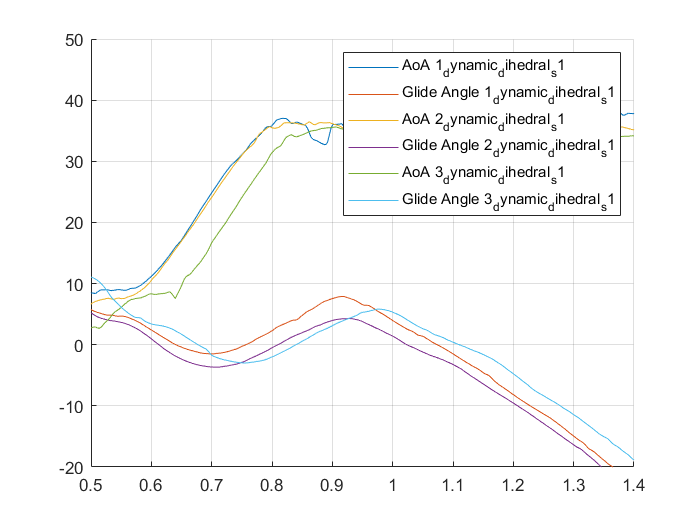

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.AoA, 'DisplayName',"AoA "+i);
    plot(d.t, d.glide_angle, 'DisplayName', "Glide Angle "+i)
end
hold off
legend
ylim([-20,50])
xlim([0.5,1.4])
grid("on")

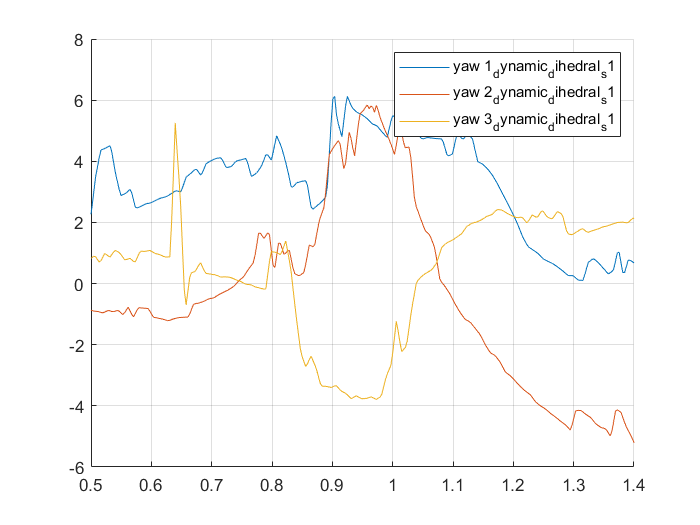

clf
hold on
for i = file_names
    d = data.("a"+i);
    rm = rmmissing(d.yaw);
    plot(d.t, abs(d.yaw)+ rm(1), 'DisplayName', "yaw "+i)
end
hold off
legend
xlim([0.5,1.4])
grid("on")

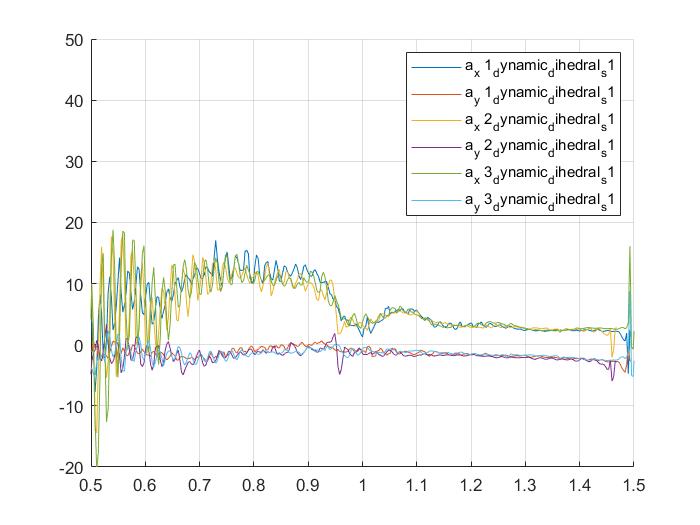

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.a_x, 'DisplayName',"a_x "+i);
    plot(d.t, d.a_y, 'DisplayName', "a_y "+i)
end
hold off
legend
ylim([-20,50])
xlim([0.5,1.5])
grid("on")

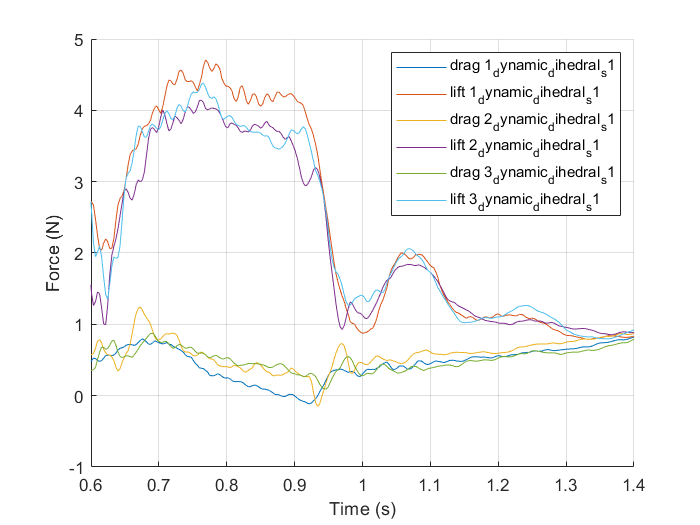

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, -d.drag, 'DisplayName',"drag "+i);
    plot(d.t, d.lift, 'DisplayName',"lift "+i);
    %plot(d.t, d.lift./d.drag)
end
hold off
legend
xlim([0.6,1.4])
xlabel("Time (s)")
ylabel("Force (N)")
grid("on")

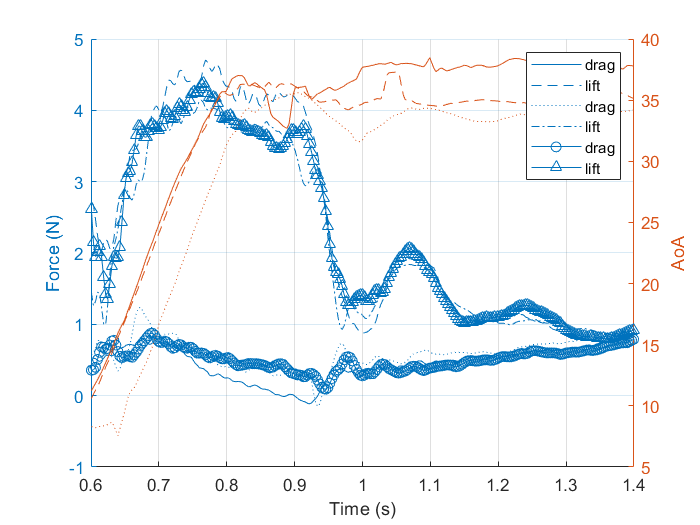

clf
storedrag = [];
storelift = [];
storeaoa = [];

hold on

for i = file_names
    yyaxis left
    d = data.("a"+i);
    d = d(d.t>0.6, :);
    d = d(d.t<1.4, :);
    
    plot(d.t, mean(-d.drag,2), 'DisplayName',"drag");
    plot(d.t, mean(d.lift,2), 'DisplayName',"lift");
    ylabel("Force (N)")
    yyaxis right
    ylabel("AoA")
    plot(d.t, mean(d.AoA,2), "HandleVisibility","off");
end
hold off
legend
xlabel("Time (s)")
grid("on")

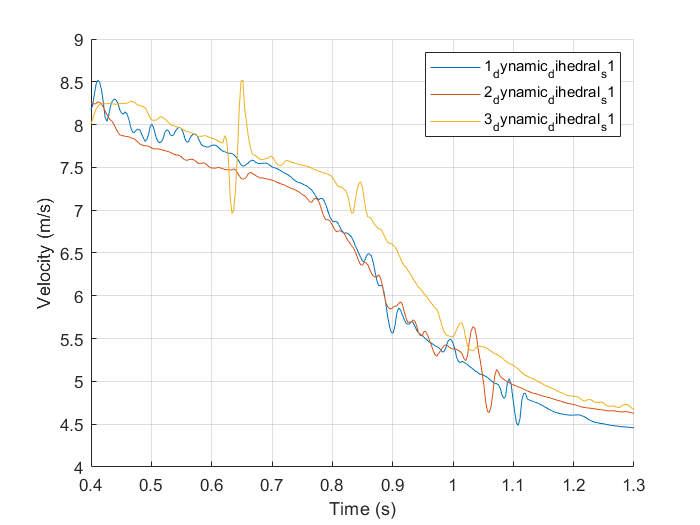

clf
hold on
for i = file_names
    d = data.("a"+i);
    plot(d.t, d.v,'DisplayName',""+i);
end
hold off
legend
xlim([0.4,1.3])
xlabel("Time (s)")
ylabel("Velocity (m/s)")
grid("on")

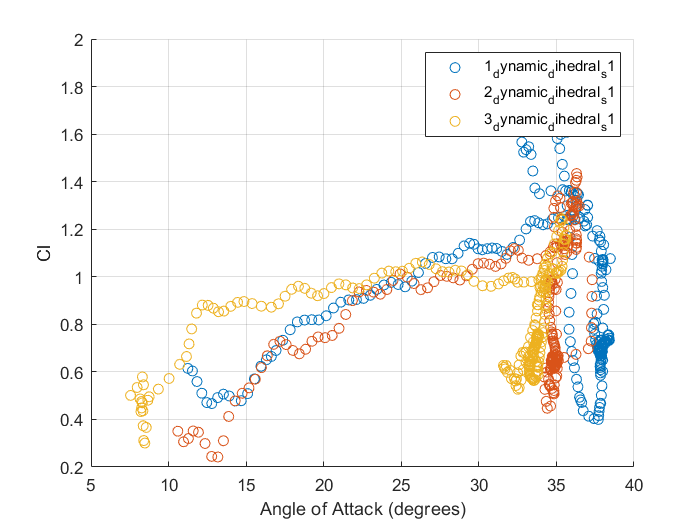

clf
hold on
A = 0.15*0.8;
store = [];
for i = file_names
    d = data.("a"+i);
    d = d(d.t>0.6, :);
    d = d(d.t<1.3, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    scatter(d.AoA, Cl, 'DisplayName',""+i)
end
hold off
legend
xlabel("Angle of Attack (degrees)")
ylabel("Cl")
grid("on")

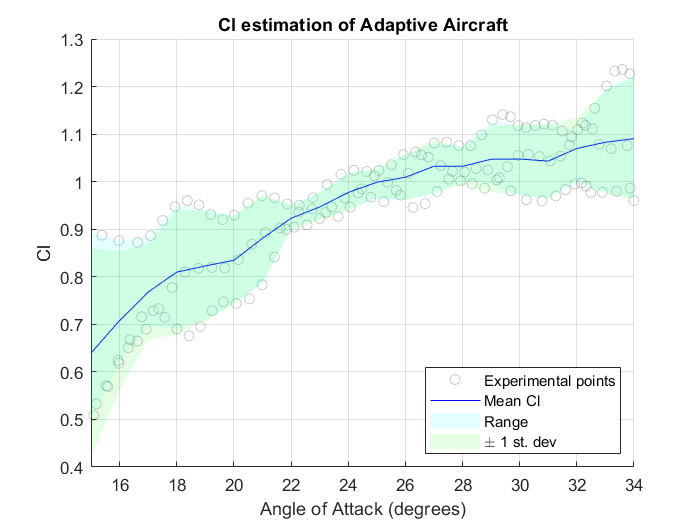

clf
A = 0.15*0.8;
min_r = 15;
max_r = 34;
storecl = [];
storeaoa = [];
hold("on")
enumerate = @(values) [1:length(values)];
for i = enumerate(file_names)
    d = data.("a"+file_names(i));
    d = d(d.t>0.62, :);
    d = d(d.t<0.85, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    ClInterp = interp1(d.AoA, Cl, min_r:max_r);
    storecl(:, i) = ClInterp;
    storeaoa(:, i) = min_r:max_r;
    scatter(d.AoA, Cl, "black","MarkerEdgeAlpha",0.2, 'HandleVisibility',"off");
end

%dummy scatter for legend
scatter(d.AoA-100, Cl-100, "black","MarkerEdgeAlpha",0.2);

plot(min_r:max_r, mean(storecl,2), "blue")

high =  max(storecl,[],2);
low = min(storecl,[],2);
x = (min_r:max_r)';
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P1 = patch(patchx, patchy, 'r');
set(P1, 'facecolor', "cyan", 'edgecolor', 'none');
set(P1, 'facealpha', 0.1);

high =  mean(storecl,2) + std(storecl,[],2);
low = mean(storecl,2) - std(storecl,[],2);
x = (min_r:max_r)';
patchx = [x; x(end:-1:1)];
patchy = [low; high(end:-1:1)];
P2 = patch(patchx, patchy, 'r');
set(P2, 'facecolor', "green", 'edgecolor', 'none');
set(P2, 'facealpha', 0.1);

hold("off")
xlabel("Angle of Attack (degrees)")
ylabel("Cl")
grid("on")
xlim([min_r,max_r])
legend("Experimental points", "Mean Cl", "Range","\pm 1 st. dev", "Location","southeast")
title("Cl estimation of Adaptive Aircraft")

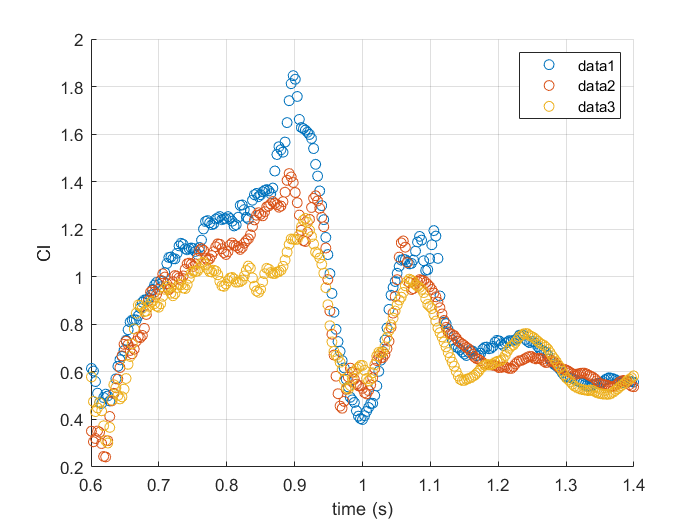

clf
hold on
A = 0.15*0.8;
for i = enumerate(file_names)
    d = data.("a"+file_names(i));
    d = d(d.t>0.6, :);
    d = d(d.t<1.4, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    scatter(d.t, Cl);
end
hold off
legend
xlabel("time (s)")
ylabel("Cl")
grid("on")

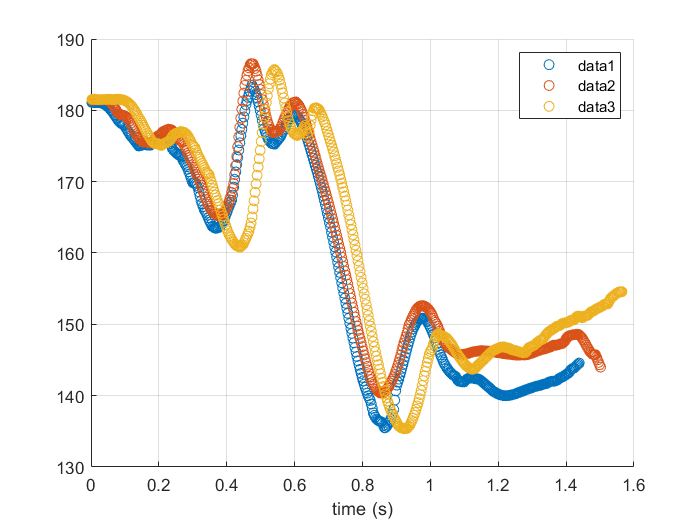

clf
hold on
A = 0.15*0.8;
for i = file_names
    d = data.("a"+i);
    d.left_rel_z = data.("a"+i).leftz - data.("a"+i).midz;
    d.left_rel_y = data.("a"+i).lefty - data.("a"+i).midy;
    d.left_rel_x = data.("a"+i).leftx - data.("a"+i).midx;
    d.right_rel_z = data.("a"+i).rightz - data.("a"+i).midz;
    d.right_rel_y = data.("a"+i).righty - data.("a"+i).midy;
    d.right_rel_x = data.("a"+i).rightx - data.("a"+i).midx;
        
    data.("a"+i).angles = 180 - atand(d.right_rel_z./d.right_rel_x) + atand(d.left_rel_z./d.left_rel_x);
    scatter(d.t, data.("a"+i).angles);
end
hold off
legend
xlabel("time (s)")
grid("on")

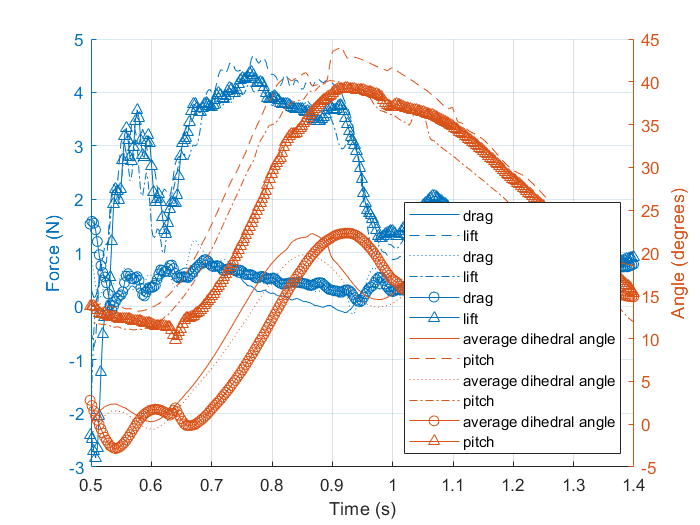

clf
storedrag = [];
storelift = [];
storeaoa = [];
storepitch = [];
hold on

for i = enumerate(file_names)
    yyaxis left
    d = data.("a"+file_names(i));
    d = d(d.t<1.4, :);
    plot(d.t, mean(-d.drag,2), 'DisplayName',"drag");
    plot(d.t, mean(d.lift,2), 'DisplayName',"lift");
    ylabel("Force (N)")
    yyaxis right
    ylabel("Angle (degrees)")
    plot(d.t, mean(-(d.angles-180)/2,2), 'DisplayName',"average dihedral angle");
    plot(d.t, mean(d.pitch,2), 'DisplayName',"pitch");

end
hold off
legend('Location', "southeast")
xlabel("Time (s)")
xlim([0.5,1.4])
grid("on")